# **Generate Template Matching**

Author: Virly Y. Ananda (MATLAB-Dynamo Integrated)

Affiliation: Department of Molecular Biology, Massachusetts General Hospital

Date: June 14, 2023

Template matching is one of the most common technique in object detection. This technique is especially useful in the Cryo-EM/ET community where object in a molecular level can be detected (e.g., protein, ribosomes, etc.). Here we documented a walkthrough on locating Cryo-EM Single-Particle ribosome on a tomogram.

**Step 1: Install Dynamo package on MATLAB and activate**

% Go to working directory: Pathway is contextual on how you install MATLAB
% and Dynamo package.
cd /Users/virly/Documents/MATLAB/
% Unzip .tar file of Dynamo package
untar dynamo-v-1.1.532_MCR-9.9.0_GLNXA64_withMCR.tar
% Activate Dynamo package
run /Users/virly/Documents/MATLAB/dynamo_activate.m

**Step 2: Extract and adjust ribosome**

Here we adjusted map resolution to low-res of 20A. To achieve this, we implemented the Nyquist limit to obtain our target resolution. Formula as $\textrm{FP}=\frac{\left(s\textrm{pacing}\;\textrm{size}*\textrm{voxel}\;\textrm{size}\;\textrm{in}\;\;\AA \right)\;}{\textrm{target}\;\textrm{resolution}\;\textrm{in}\;\AA }$.

Once FP is calculated, we then use this as input in band filter on dynamo_mapview.

% Unzip structure map.
% Extract structure map from EMDB
dynamo_emdb(2847);
% Adjust FP resolution of original map to low resolution (20A).
dpkdev.legacy.dynamo_mapview('emd_2847.map');

% This will prompt us to Dynamo GUI where we can input our FP (15.8602).

On the GUI, under** Operations** > **band**, input FP score and click** band**.

On the GUI, under **File I/O**, rename the *temp.em* (or not) file and click on **save**. Close the GUI.

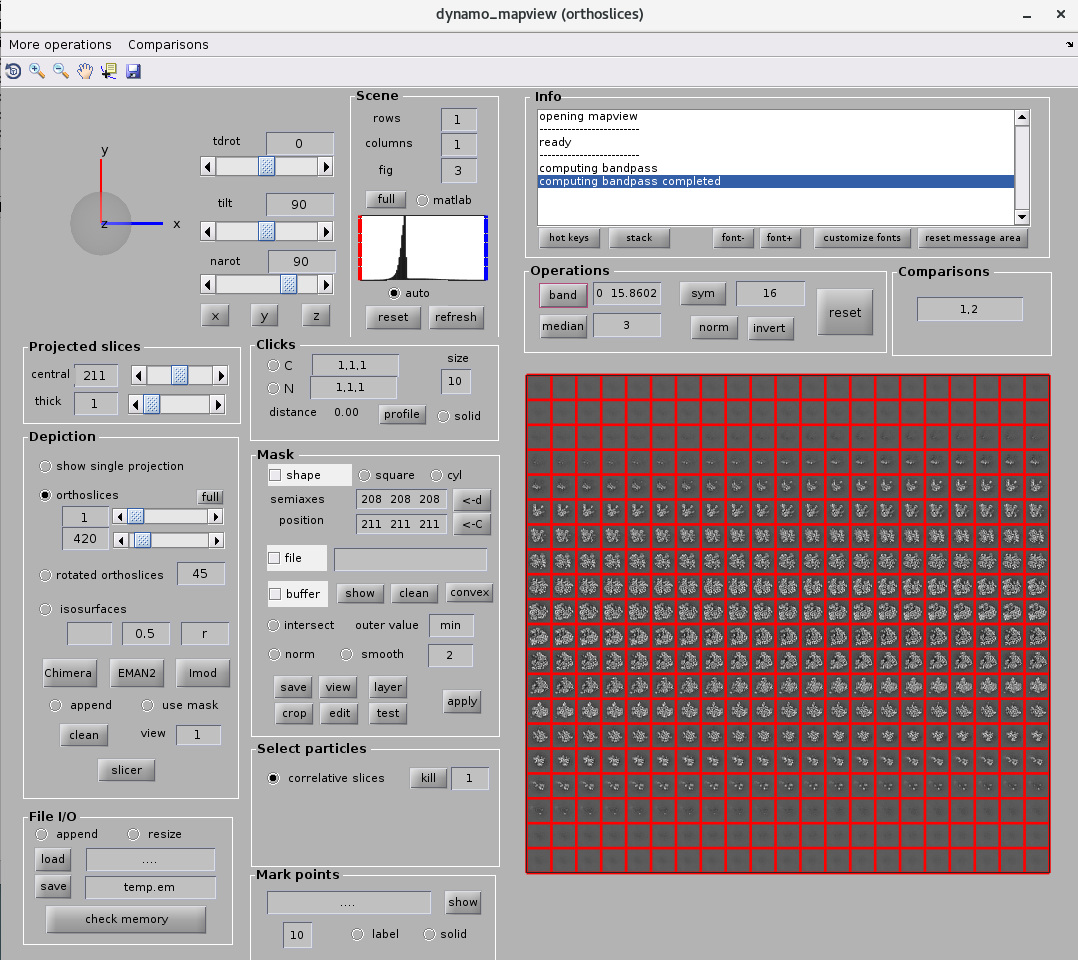

% Read lowres map we just adjusted
ribosomelowres = dread('temp.em');
% Adjust size of ribosome with our current tomogram
newVol = dynamo_rescale(ribosomelowres,0.75525,10.26);
% Invert map
ribosomeFinalInvert = -newVol;
% Convert map to .MRC format
dwrite(ribosomeFinalInvert,'ribosomeWT.mrc');

**Step 3: Run template matching**

% cryoCARE restored tomogram is used. 
pts = dyamo_match('bin4_b001ts001_cryoCARE.rec', 'ribosomeWT.mrc', 'outputFolder', 'cs30', 'ytilt', [-39,36], 'sc', [256,256,256], 'cr', 360, 'cs', 30);

Several issues were encountered upon generating template matching, based our assumption this could be due to:

- Type of Tomogram: Prioritize using floating point data.

- Size of Tomogram: High number of slices could slow down and even crash the entire process.

Template matching process was ran overnight with cryoCARE restored tomogram (bin4).

**Step 3: Optimize template matching**

To optimize our search, we implemented maximum cross correlation search.

% Evaluate our template matching result.
pts.showCC;

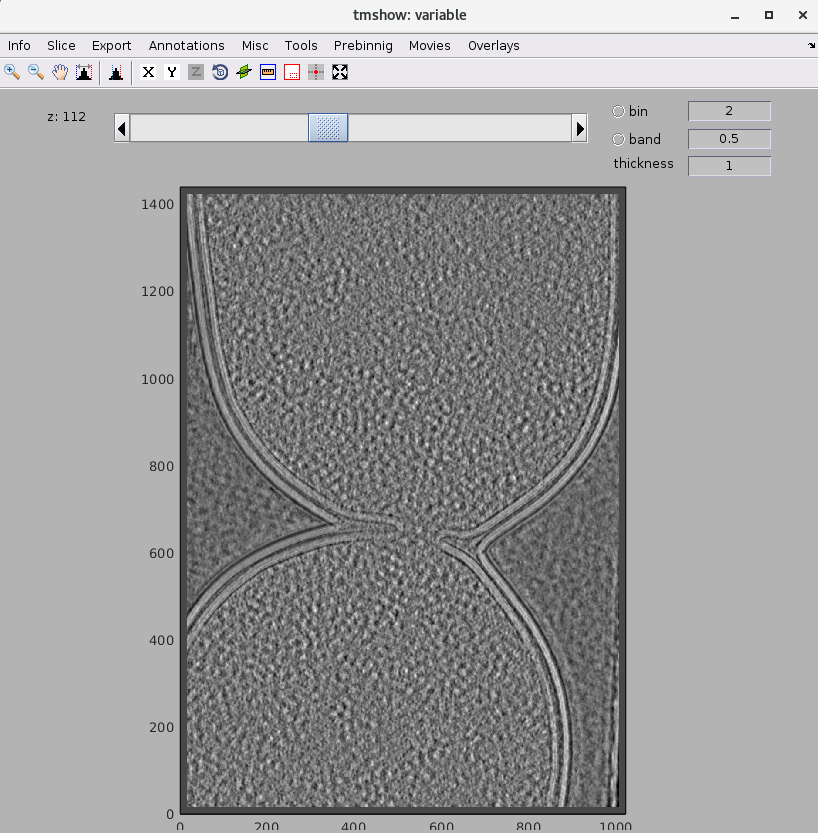

Based on the figure shown above, we notice several circular highlighted areas that are presumably ribosome features on the tomogram.

% Plot cross correlation profile. Find the most correlated features of
% ribosome by selecting the area above curve line.
pts.peaks.plotCCPeaks('sidelength',31);

Once we have an initial point, we optimized our search again:

% Implement this on Ecoli WT
pts = dread('cs30.TM/process.mat');
pts.peaks.settings.maxNumberPeaks.value = Inf;
myWTTableMax = pts.peaks.computeTable('mcc', 0.177);
dtplot(myWTTableMax,'pf','oriented_positions');

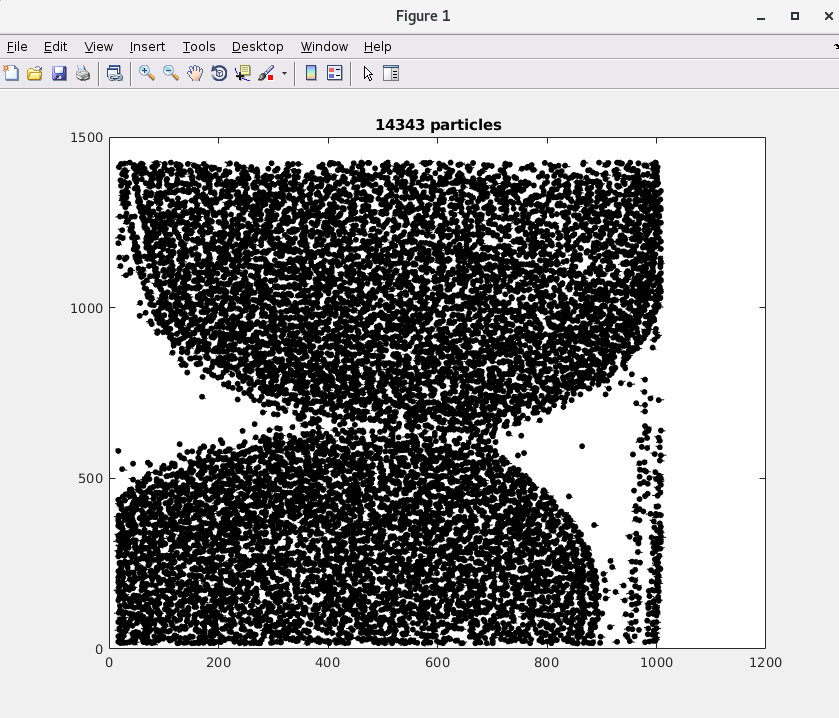

Outliers (false positives) can clearly be seen here. We can also see that each point has different rotation peak (which is something that should be normal considering we are using single-particle ribosome as a template).

%%% View Ecoli WT max on dtmslice
dwrite(myWTTableMax,'myWTTableMax.tbl');
dmimport -t myWTTableMax.tbl -c ctWTs -i 1 -mn myWTTableMaxModel
dtmslice bin4_b001ts001_cryoCARE.rec -c ctWTs


To remove outliers detected on our tomogram, we created an in-house script to generate what we adjusted on Dynamo GUI.

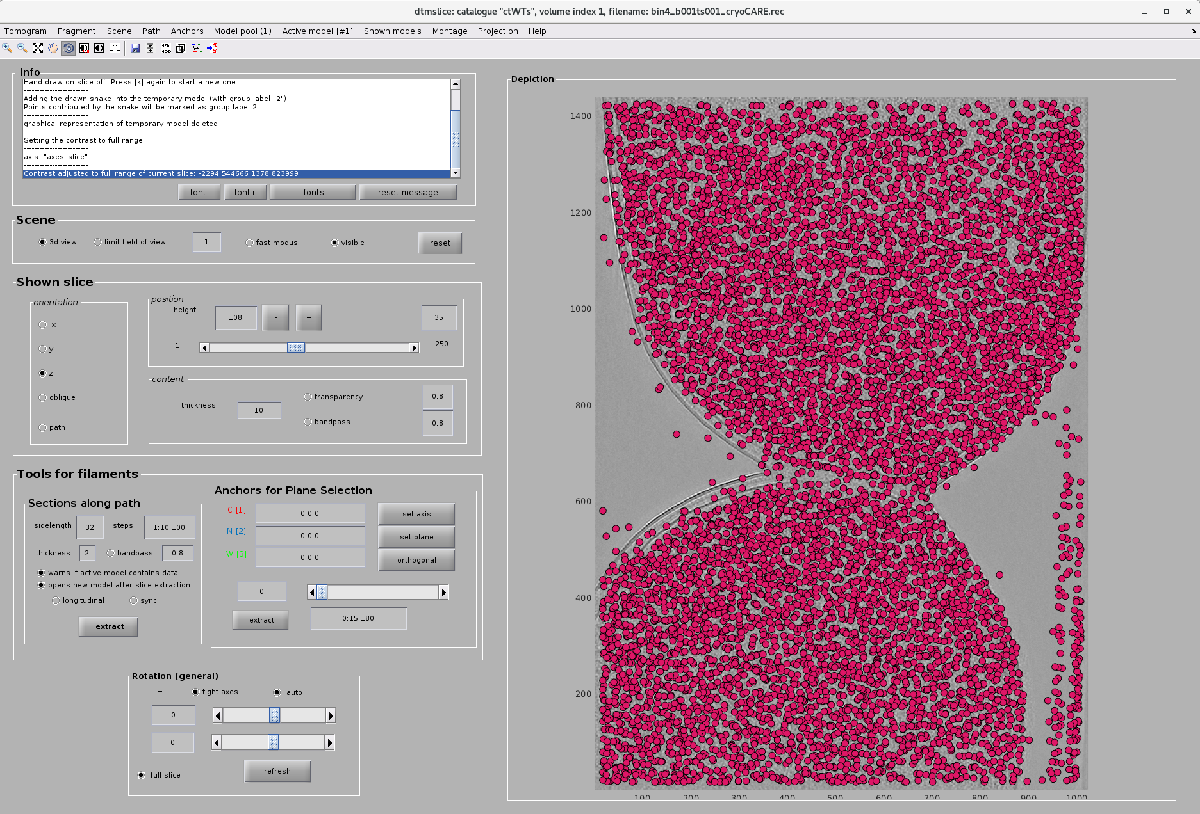

To adjust contrast of the tomogram, to the top panel and select Fixes contrast (next to rotation icon).

If model points are not present, go to **Model pool** > **Create new model (type): Surface**.

Go to **Active model** > **Change name of Active model**. Boundary line will be created on this model.

Go to **Shown models** > **Show only model 2**. This should be the new model (active model).

Due to the crowded points on the original model, we created boundary line where the original model is not visible.

Press **Ctrl+C** to create boundary line on 1 Z slice. Focus on the slice that show the most visible area, this can reduce certain bias when filter out points.

Click on the save icon on the top panel.

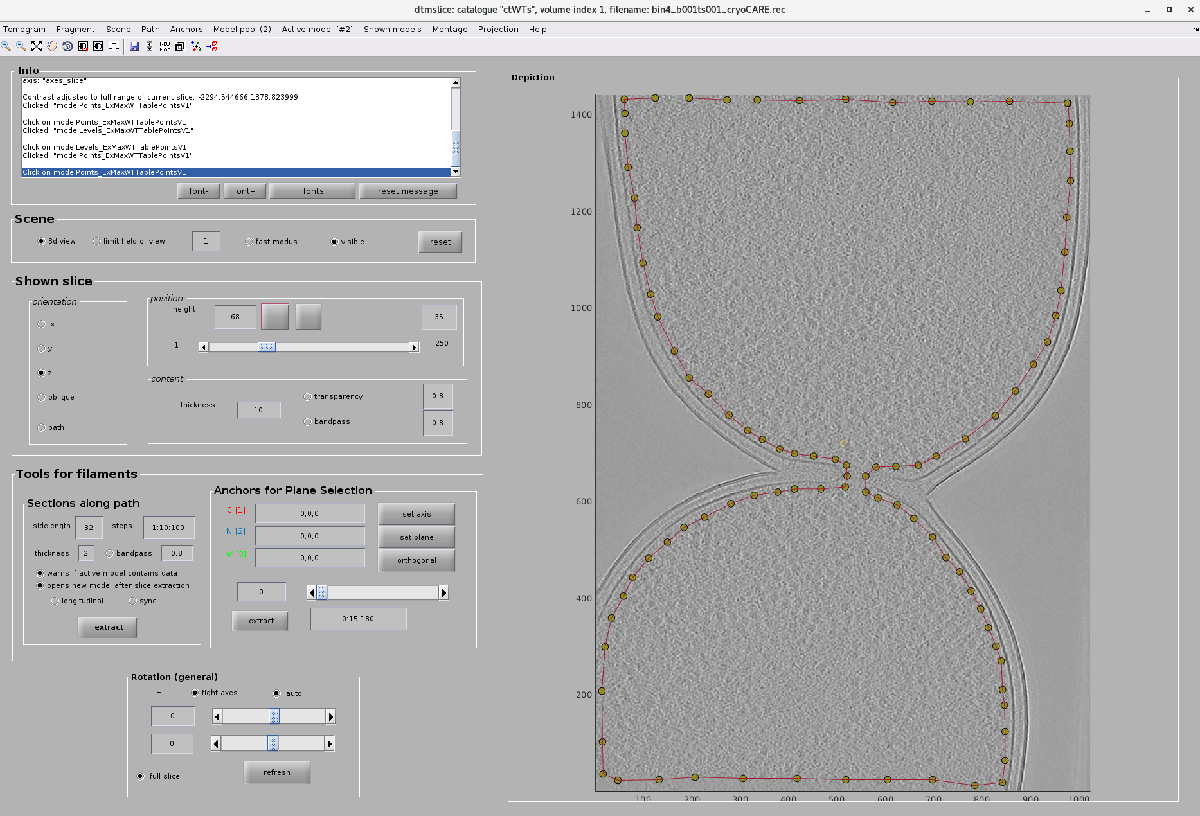

Once we have our 2 models: Original model that contains outliers and the boundary line model where we labeled a polygon-like line, we can run the script.

% Plotting original table with outliers and without outliers
% Load the original model to a new output directory
dcmodels ctWTs -nc myWTTableMaxModel -ws output
% Load the first data from the ouput directory (this refers to the original
% PonBTable1001 model:
p = dread(output.files{1});
pXY = p.points(:,[1,2]);
% Load the boundary model to a new output directory
dcmodels ctWTs -nc ExMaxWTTablePointsV1 -ws output
% Load the second data from the output directory (this refers to the
% boundary PonB_Surf1 model:
b = dread(output.files{1});
% Extract the points data based on XY plane (Z) since we created the
% boundary line on XY plane. Apply this to both boundary and original
% model:
bXY = b.points(:,[1,2]);
% Use polygon to extract out the points data within the boundary line from
% boundary model:
indicesOfPinsideB = inpolygon(pXY(:,1),pXY(:,2),bXY(:,1),bXY(:,2));
% Create an empty figure:
f = figure();
% This will be our first subplot:
hs1 = subplot(2,1,1);
% Within the 1st subplot, plot out the original points model (raw model):
h = dpkgeom.plotCloud(p.points); axis equal
% Replace encircled points with points in "dot":
h.Marker = '.';
% Visualize our plot in XY plane (Z):
view([0,0,1]);
% Adjust X scale and Y(Z) scale onthe plot:
hs1.ZLim = [0,200];
hs1.XLim = [0,1000];
% Add main title:
title('Original Peaks Ecoli WT Max. Model');
% Create new variable for the second subplot (this should give you an empty plot
% below the first subplot):
hs2 = subplot(2,1,2);
% Visualize the data points when we subtract the original data with what we
% have within the boundary line:
h = dpkgeom.plotCloud(p.points(indicesOfPinsideB,:)); axis equal
% Replace the encircled points with "." points:
h.Marker = '.';
% This gives us the ability to add adjustment on the second subplot:
hold on;
% Add the boundary line here (to highlight the line):
hB = dpkgeom.plotCloud(b.points); axis equal
% Adjust the points to circles. This would make the points look bolder:
hB.Marker = 'o';
hB.LineStyle = '--';
% Adjust the color:
hB.MarkerFaceColor = 'b';
hB.Color = 'k';
% Add title
title('Peaks inside boundary');
% Visualize the second subplot on XY plane (Z):
view([0,0,1]);
axis(hs2,axis(hs1));

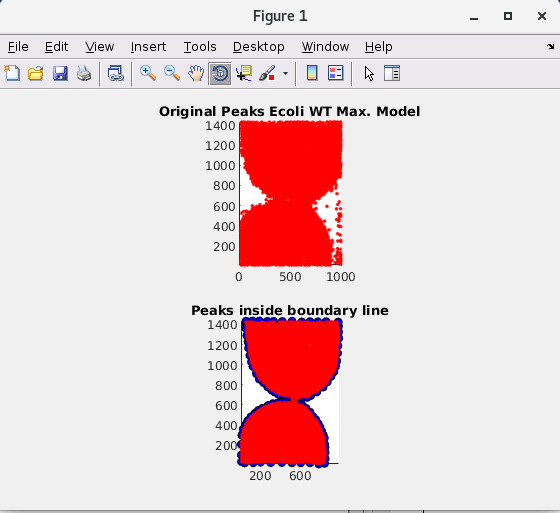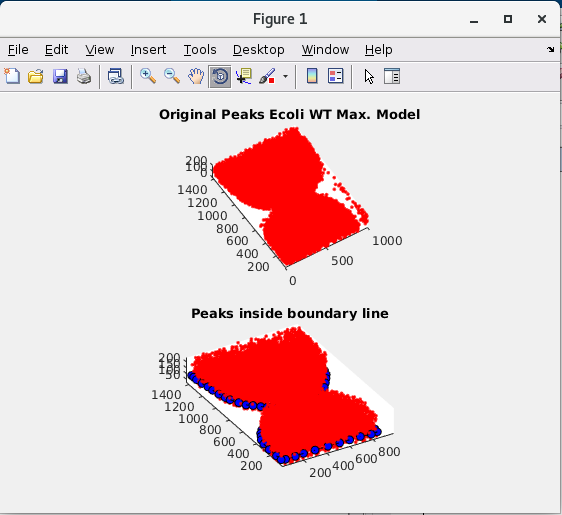

% Convert the second model to a readable format.
myWTTablePoints2 = p.points(indicesOfPinsideB,:);
dwrite(myWTTablePoints2,'myWTTablePoints2.txt');
% Import the file to catalogue as a model.
dmimport -xyz 'myWTTablePoints2.txt' -c ctWTs -i 1 -label points -mn ExMaxWTTablePointsV2

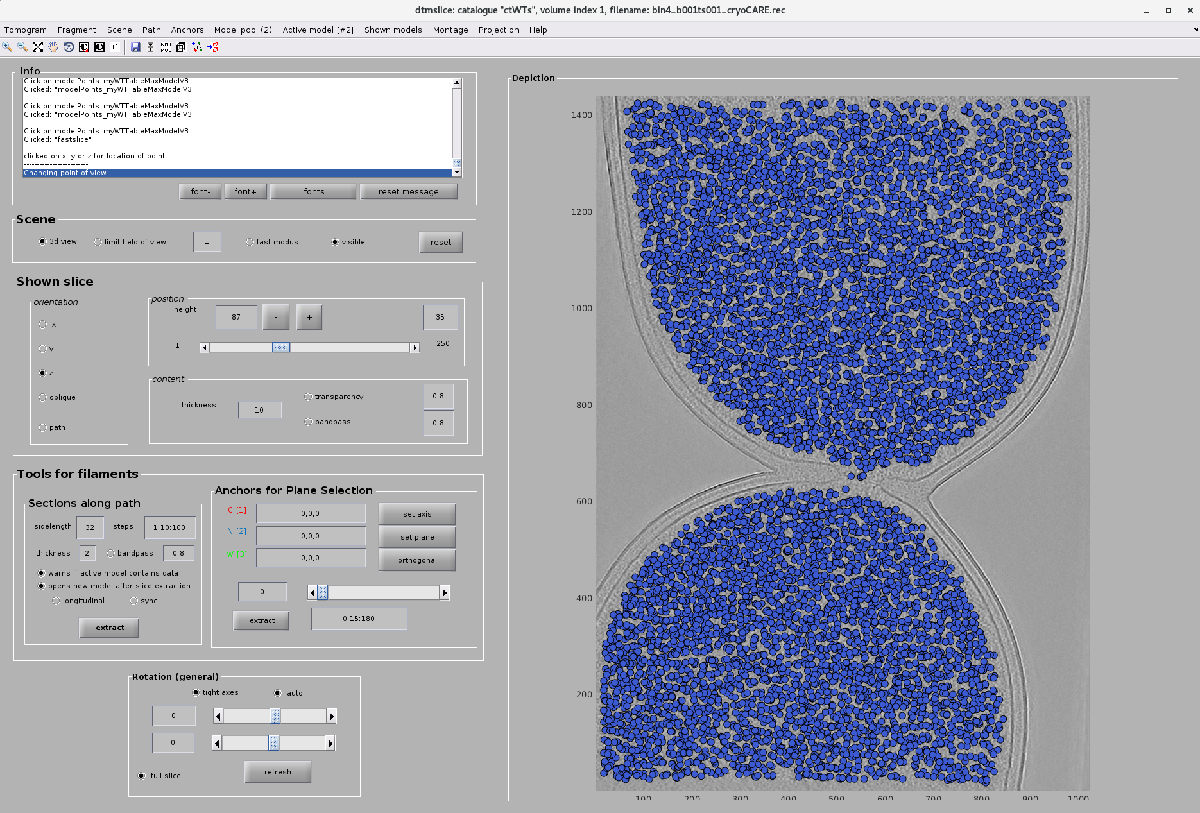

On the top panel, go to **Active Model** > **Update Crop Points**. Save file.

To convert this model into a table format, go to** Active Model **> **Edit Active Model **on the top panel.

On top of the panel, click on the table icon to convert to table format.

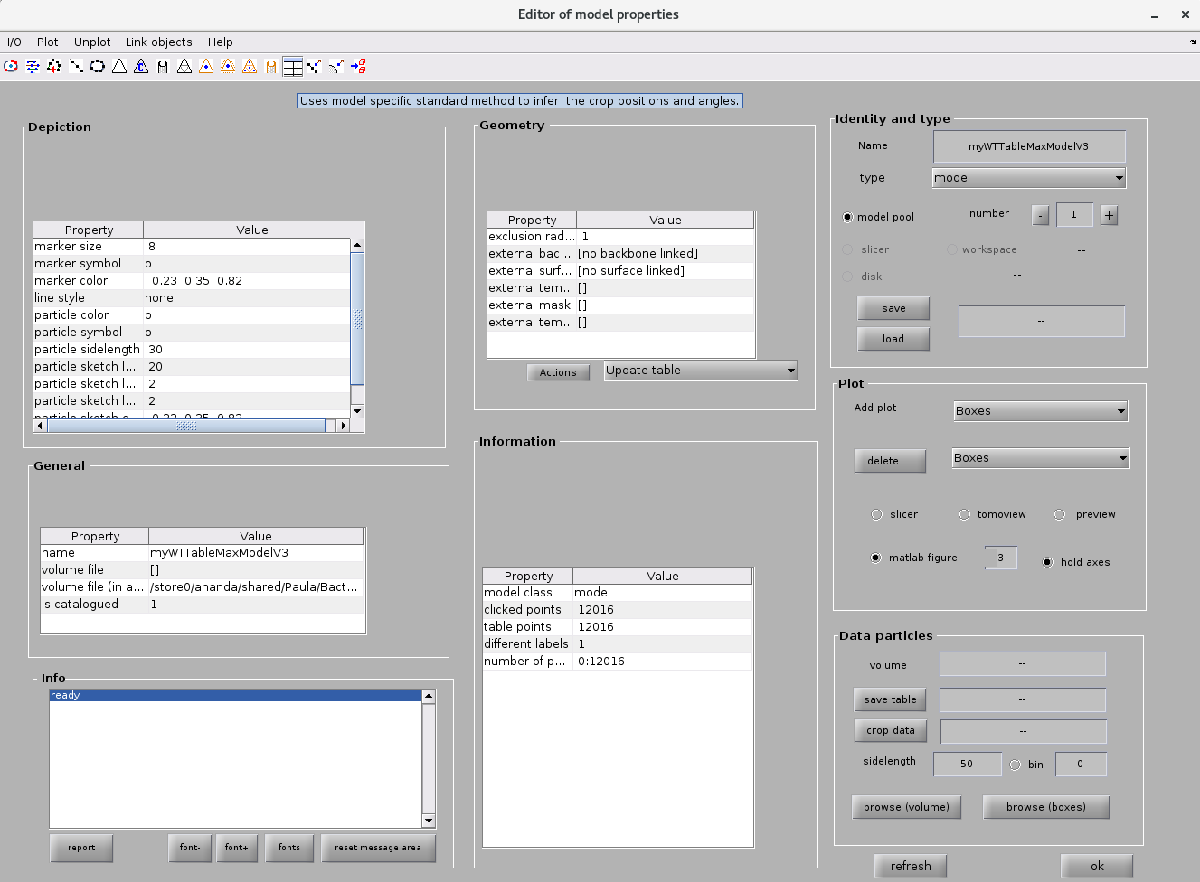

What we noticed:

- Rotation angles are excluded when crop points are updated.

- Side effect includes ribosome model without rotation information.

To solve this issue, we came up with filtering loop that extract X,Y,Z coordinates of ribosome as unique ID and sort out any ribosomes that are present both in the original and updated models.

% Read the table generated from above model.
newWTMaxDataV3 = dread('myWTTableMaxModelV3.tbl');

%%% Authors: Virly Y. Ananda, Paula P. Navarro
%%% Date: March 24, 2023
%%% Affiliation: Massachusetts General Hospital

% Original table after boundary line applied
OT = myWTTableMax;
% Table after outliers removed from original table
ET = newWTMaxDataV3;

% Filter unique information: XYZ spatial locations
xvalues = ET(:,24);
yvalues = ET(:,25);
zvalues = ET(:,26);

xOriginalValues = OT(:,24);
yOriginalValues = OT(:,25);
zOriginalValues = OT(:,26);

myIndexes = [];

for i=1:length(xvalues)
    indX = find(xOriginalValues==xvalues(i));
    
    for a=1:length(indX)
        if yOriginalValues(indX(a))==yvalues(i) && zOriginalValues(indX(a))==zvalues(i)
            myIndexes(end+1)=indX(a);
        else
            disp('Value did not match');
        end
    end
end

% Apply
WTMaxAngleExcludedTable = OT(myIndexes,:);

Updated template matching table with angle information is now updated.